pose_base = Pose2.hat([0, 0, -pi/2]);

% Here we will assume antagonistic arm
% Placeholder radii and summing matrix
rho_outer = 0.08;
rho_inner = 0.015;
rhos = [-rho_outer, rho_inner, rho_outer];
mat_A = [
1, 1, 1;
0, 0, 0;
-rhos;
];

% Antagonistic muscle profiles
f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_bellow};

l_0 = 0.5;
N_nodes = 10;

% Combine the design parameters into a struct
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = pose_base;
struct_design.rhos = rhos;

p_bounds = [50; 100; 50];

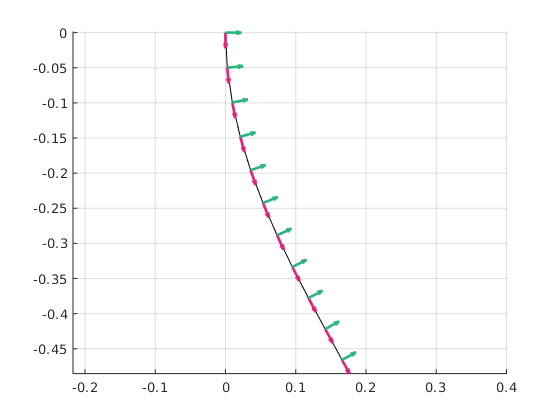

% Specify the shape of the arm
a = -1;
b = 1;

l = 0.5;
f_affine_curvature = @(s) [
    l*ones(size(s));
    zeros(size(s));
    a*s + b
];
s = linspace(0, 1, N_poses);
poses = f_calc_poses(pose_base, f_affine_curvature, N_nodes);
segment_twists = f_affine_curvature(s);

ax = axes(figure());
plot_poses(poses, ax);
grid on
set(gcf, "visible", true)

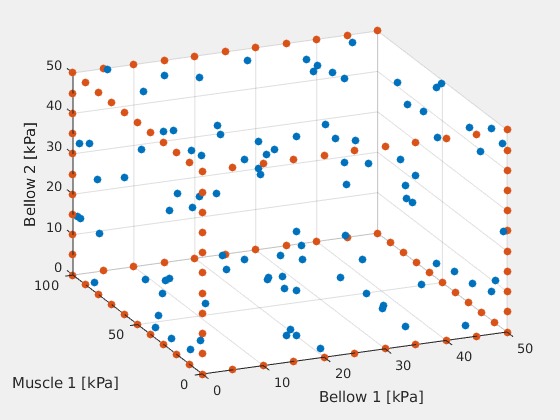

% Sample points along the boundaries of the pressure space
N_points_on_edge = 10;
N_points_on_faces = 100;
ps_faces = sample_faces_of_cuboid(N_points_on_faces, p_bounds);
ps_edges = sample_edges_of_cuboid(N_points_on_edge, p_bounds);

figure("visible", true)
hold on
scatter3(ps_faces(1, :), ps_faces(2, :), ps_faces(3, :), "filled");
scatter3(ps_edges(1, :), ps_edges(2, :), ps_edges(3, :), "filled");
grid on
xlabel("Bellow 1 [kPa]")
ylabel("Muscle 1 [kPa]")
zlabel("Bellow 2 [kPa]")
view(-23, 28)

N_points_on_edges = length(ps_edges);
forces_edges = zeros(3, N_nodes, N_points_on_edges);
forces_faces = zeros(3, N_nodes, N_points_on_faces);

for i = 1 : N_points_on_edges
    p_i = ps_edges(:, i);
    [~, forces_edges(:, :, i)] = calc_reaction_wrench(segment_twists, p_i, struct_design);
end

for i = 1 : N_points_on_faces
    p_i = ps_faces(:, i);
    [~, forces_faces(:, :, i)] = calc_reaction_wrench(segment_twists, p_i, struct_design);
end

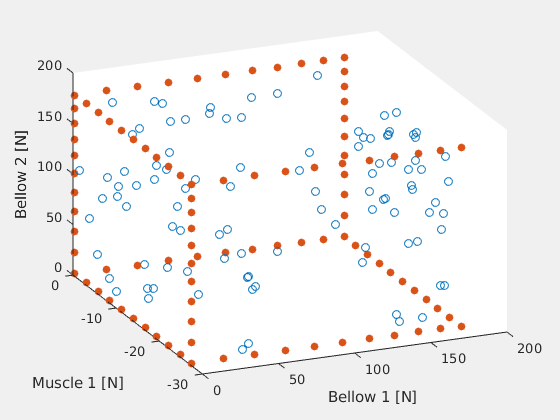

figure("visible", true);
hold on
scatter3(squeeze(forces_faces(1, end, :)), squeeze(forces_faces(2, end, :)), squeeze(forces_faces(3, end, :)))
scatter3(squeeze(forces_edges(1, end, :)), squeeze(forces_edges(2, end, :)), squeeze(forces_edges(3, end, :)), "filled")
xlabel("Bellow 1 [N]")
ylabel("Muscle 1 [N]")
zlabel("Bellow 2 [N]")
view(-23, 28)

[edges_af, edges_am] = compute_reaction_paths(ps_edges, segment_twists, struct_design);
[faces_af, faces_am] = compute_reaction_paths(ps_faces, segment_twists, struct_design);

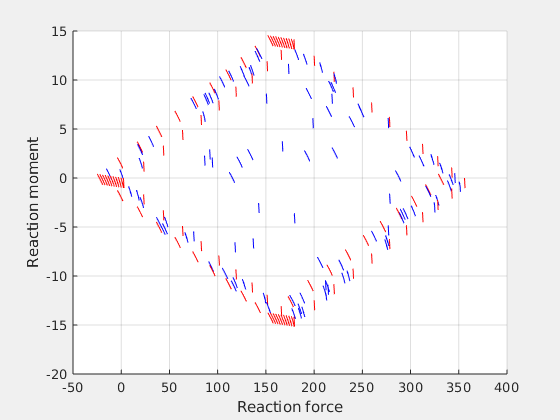

mat_s = repmat(s, [N_points_on_edges, 1]);

figure("visible", true)
hold on
grid on
plot3(faces_af', faces_am', s, 'b');
plot3(edges_af', edges_am', s, 'r');
xlabel("Reaction force")
ylabel("Reaction moment")
zlabel("S")

view(-28, 28)

function poses = f_calc_poses(g_0, f_segment_twists, N_poses)
    s = linspace(0, 1, N_poses);
    mat_segment_twists = f_segment_twists(s);
    poses = calc_poses(g_0, mat_segment_twists);
end

function [paths_af, paths_am] = compute_reaction_paths(ps, segment_twists, struct_design)
    N_ps = size(ps, 2);
    N_poses = size(segment_twists, 2);

    mat_rxns_3d = zeros(3, N_poses, N_ps);
    paths_af = zeros(N_poses, N_ps);
    paths_am= zeros(N_poses, N_ps);
    
    for i = 1 : N_ps
        % For each pressure, compute the corresponding reactions
        mat_rxns_3d(:, :, i) = calc_reaction_wrench(segment_twists, ps(:, i), struct_design);
    end
    
    [paths_af, paths_am] = mat_wrenches_to_paths(mat_rxns_3d);
end

function [paths_f, paths_m] = mat_wrenches_to_paths(mat_wrenches)
    N_ps = size(mat_wrenches, 3);
    N_poses = size(mat_wrenches, 2);

    paths_f = zeros(N_poses, N_ps);
    paths_m= zeros(N_poses, N_ps);
    
    for i = 1 : N_poses
        paths_f(i, :) = squeeze(mat_wrenches(1, i, :));
        paths_m(i, :) = squeeze(mat_wrenches(3, i, :));
    end
end

function points = sample_edges_of_cuboid(N_points_on_edge, scales)
    % Returns points on the edges and vertices of a N-dimensional cube
    N_dims = length(scales);
    N_edges = N_dims * 2^(N_dims - 1);
    N_points = N_points_on_edge * N_edges;

    bitstrings = (dec2bin(1:2^(N_dims-1)) - '0')';
    %points = rand([N_dims, N_points]);
    points = [];
    t = linspace(0, 1, N_points_on_edge+1);
    t = t(2:end-1);
    for i_dim = 1 : N_dims
        % Create points for all vertices that has this dimension going 0-1
        for i_edge = 1 : length(bitstrings)
            bitstring_i = bitstrings(:, i_edge);
            points_edge_i = repmat(bitstring_i, 1, length(t));
            points_edge_i(i_dim, :) = t;
            points = [points, points_edge_i];
        end
    end

    vertices = (dec2bin(0:(2^N_dims - 1)) - '0')';
    points = [points, vertices];

    points = diag(scales) * points;
end

function points = sample_faces_of_cuboid(N_points, scales)
    N_dims = length(scales);

    faces = randi([1, 2*N_dims], [1, N_points]);
    points = rand([N_dims, N_points]);
    for i = 1 : N_points
        face_i = faces(i); % Face whose point value to fix at 1 
        fixed_val = 0;
        if face_i > N_dims
            fixed_val = 1;
            face_i = mod(face_i, N_dims);
            face_i = face_i+1;
        end
        points(face_i, i) = fixed_val;
    end

    points = diag(scales) * points;
end